clear all
close all
clc

A1=2;
A2=2;
A4=2;

q1=0;
q2=0;
q3=0;

L(1) = Link('revolute','d',0,'alpha',0,'a',A1,'offset',0);
L(2) = Link('revolute','d',0,'alpha',pi,'a',A2,'offset',0); %eslabon 2 --> fila 2
L(3) = Link('prismatic','theta',0,'alpha',0,'a',0,'offset',0);
L(3).qlim = [0,2];
L

 
L = 
 theta=q1, d=          0, a=          2, alpha=          0, offset=          0 (R,stdDH)
 theta=q2, d=          0, a=          2, alpha=      3.142, offset=          0 (R,stdDH)
 theta=          0, d=q3, a=          0, alpha=          0, offset=          0 (P,stdDH)



%unir links 'eslabones'
robotscara = SerialLink(L,'name','Scara')

 
robotscara = 
 
Scara (3 axis, RRP, stdDH, fastRNE)                              
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          2|          0|          0|
|  2|         q2|          0|          2|      3.142|          0|
|  3|          0|         q3|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


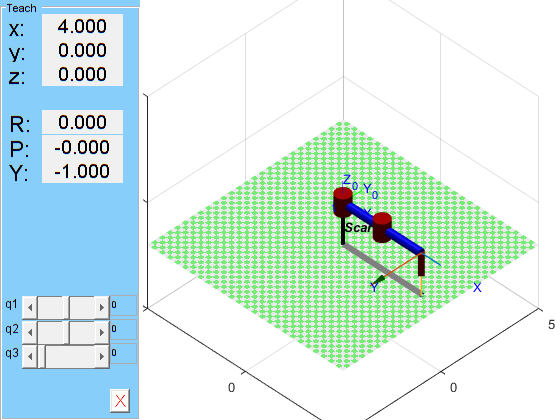


robotscara.tool = transl(0,0,0);
%robotscara

q = [0 0 0];  % Ángulos de las articulaciones

% Define el espacio de trabajo (ajusta los valores según sea necesario)
limites_espacio_trabajo = [-5 5 -5 5 -2 5];

robotscara.plot(q, 'workspace', limites_espacio_trabajo);
%robotscara.plot(q,'notiles','scale',0.7, 'jaxes') %dibujar el robot
hold on 
trplot(eye(4),'rgb','length',1,'frame','0') % sistema coordenadas de la base 
axis([-5 5 -5 5 -5 5])% ajusta los ejes 
view(45, 40)% vista frente 
robotscara.teach()



TZ0 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TZ0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RZ0 = [cos(q1) -sin(q1) 0 0; sin(q1) cos(q1) 0 0; 0 0 1 0; 0 0 0 1]

RZ0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


TX1 = [1 0 0 A1; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX1 =      1     0     0     2
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX1 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]

RX1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T01 =  TZ0*RZ0*TX1*RX1

T01 =      1     0     0     2
     0     1     0     0
     0     0     1     0
     0     0     0     1




TZ1 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TZ1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RZ1 = [cos(q2) -sin(q2) 0 0; sin(q2) cos(q2) 0 0; 0 0 1 0; 0 0 0 1]

RZ1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


TX2 = [1 0 0 A2; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX2 =      1     0     0     2
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX2 = [1 0 0 0; 0 cos(pi) -sin(pi) 0; 0 sin(pi) cos(pi) 0; 0 0 0 1]

RX2 =     1.0000         0         0         0
         0   -1.0000   -0.0000         0
         0    0.0000   -1.0000         0
         0         0         0    1.0000


T12 =  TZ1*RZ1*TX2*RX2

T12 =     1.0000         0         0    2.0000
         0   -1.0000   -0.0000         0
         0    0.0000   -1.0000         0
         0         0         0    1.0000




TZ2 = [1 0 A4 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TZ2 =      1     0     2     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RZ2 = [cos(0) -sin(0) 0 0; sin(0) cos(0) 0 0; 0 0 1 0; 0 0 0 1]

RZ2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


TX3 = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

TX3 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


RX3 = [1 0 0 0; 0 cos(0) -sin(0) 0; 0 sin(0) cos(0) 0; 0 0 0 1]

RX3 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T23 =  TZ2*RZ2*TX3*RX3

T23 =      1     0     2     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



T03 = T01*T12*T23

T03 =     1.0000         0    2.0000    4.0000
         0   -1.0000   -0.0000         0
         0    0.0000   -1.0000         0
         0         0         0    1.0000
